T = readtable('vaccinations.csv','ReadVariableNames',true);

ans = 'D:\neural-networks-matlab-tasks\data'

Error using  {} 
Unable to concatenate the table variables 'iso_code' and 'date', because their types are cell and datetime.

Error in importTotalCases (line 13)
    A = T{:,2:end};

T = table2timetable(T);

T = 1×15 timetable
       date           location        iso_code    total_vaccinations    people_vaccinated    people_fully_vaccinated    total_boosters    daily_vaccinations_raw    daily_vaccinations    total_vaccinations_per_hundred    people_vaccinated_per_hundred    people_fully_vaccinated_per_hundred    total_boosters_per_hundred    daily_vaccinations_per_million    daily_people_vaccinated    daily_people_vaccinated_per_hundred
    ___________    _______________    ________    __________________    _________________    _______________________    ______________    ______________________

T = T('Afghanistan', location)

location requires one of the following:
  Antenna Toolbox
  Communications Toolbox

summary(T)

RowTimes:

    date: 1358×1 datetime
        Values:
            Min           03-Jan-2020          
            Median        11-Nov-2021 12:00:00 
            Max           21-Sep-2023          
            TimeStep      24:00:00             

Variables:

    Brazil: 1358×1 double

        Values:

            Min             1           
            Median          6.1768e+05  
            Max             7.0466e+05  
            NumMissing      76          

    Japan: 1358×1 double

        Values:

            Min             1      
            Median          18363  
            Max             74694  
            NumMissing      41     

    Mexico: 1358×1 double

        Values:

            Min             3           
            Median          3.0258e+05  
            Max             3.3452e+05  
            NumMissing      77          

    Netherlands: 1358×1 double

        Values:

  

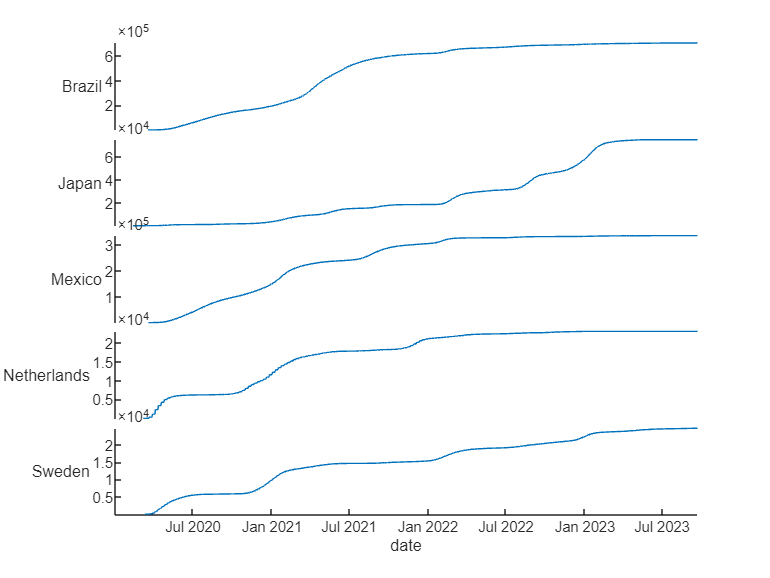

stackedplot(T)

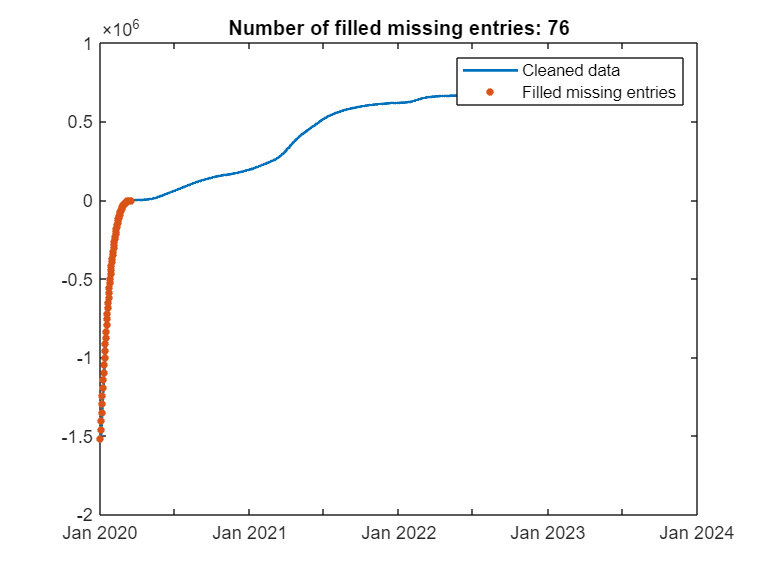

% Fill missing data
[br,missingIndices] = fillmissing(T.Brazil,'spline','SamplePoints',T.date);
% Display results
clf
plot(T.date,br,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
hold on
% Plot filled missing entries
plot(T.date(missingIndices),br(missingIndices),'.','MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])
hold off
legend

clear missingIndices

T1 = T;
T1.Brazil = br;

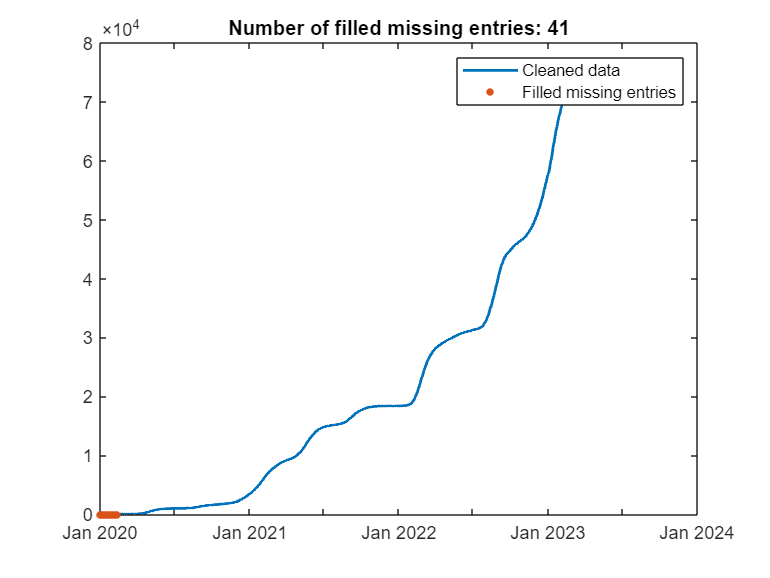

% Fill missing data
[jp,missingIndices] = fillmissing(T.Japan,'spline','SamplePoints',T.date);
% Display results
clf
plot(T.date,jp,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
hold on
% Plot filled missing entries
plot(T.date(missingIndices),jp(missingIndices),'.','MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])
hold off
legend

clear missingIndices
T1.Japan = jp;

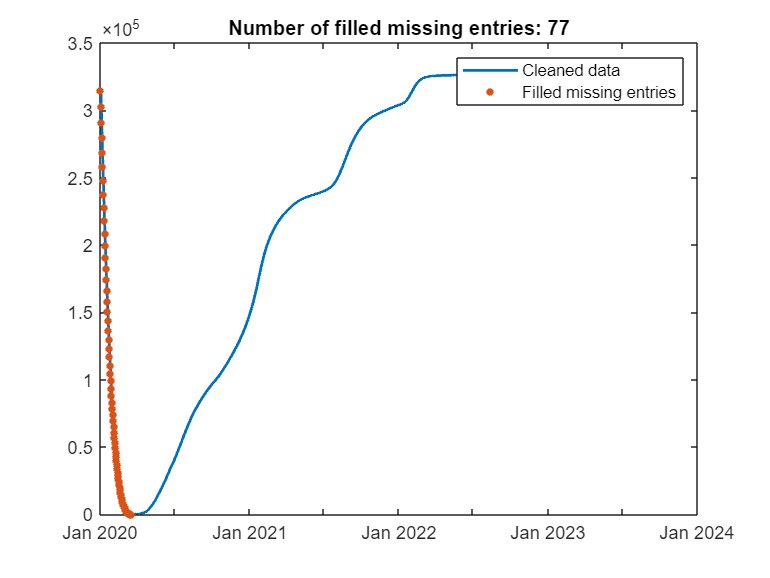

% Fill missing data
[mx,missingIndices] = fillmissing(T.Mexico,'spline','SamplePoints',T.date);
% Display results
clf
plot(T.date,mx,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
hold on
% Plot filled missing entries
plot(T.date(missingIndices),mx(missingIndices),'.','MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])
hold off
legend

clear missingIndices
T1.Mexico = mx;

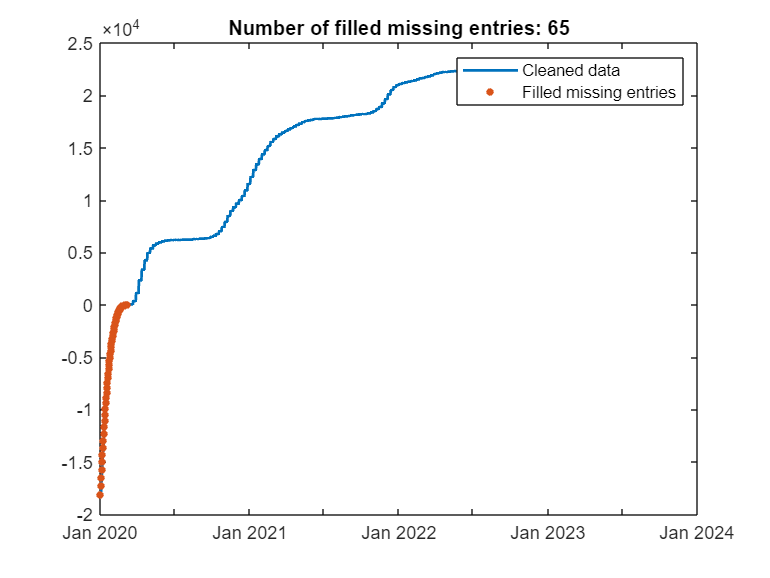

% Fill missing data
[nth,missingIndices] = fillmissing(T.Netherlands,'spline','SamplePoints',T.date);
% Display results
clf
plot(T.date,nth,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
hold on
% Plot filled missing entries
plot(T.date(missingIndices),nth(missingIndices),'.','MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])
hold off
legend

clear missingIndices
T1.Netherlands = nth;

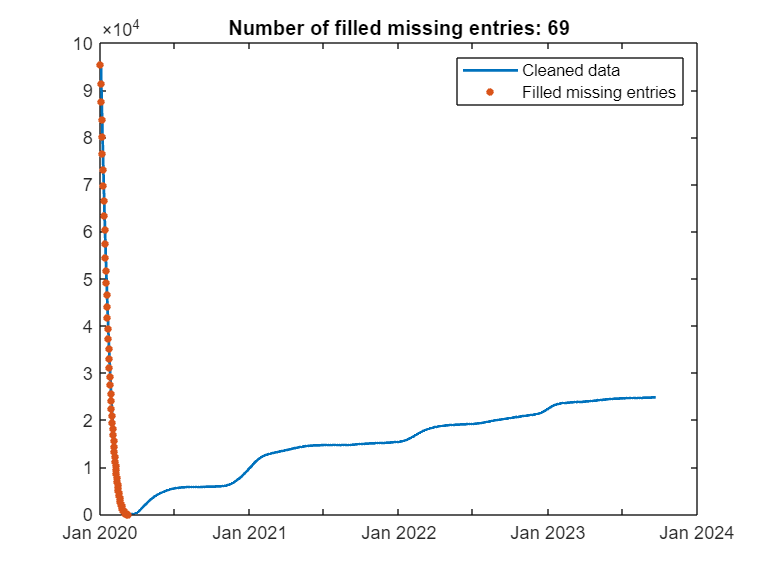

% Fill missing data
[sw,missingIndices] = fillmissing(T.Sweden,'spline','SamplePoints',T.date);
% Display results
clf
plot(T.date,sw,'Color',[0 114 189]/255,'LineWidth',1.5,'DisplayName','Cleaned data')
hold on
% Plot filled missing entries
plot(T.date(missingIndices),sw(missingIndices),'.','MarkerSize',12,'Color',[217 83 25]/255,'DisplayName','Filled missing entries')
title(['Number of filled missing entries: ' num2str(nnz(missingIndices))])
hold off
legend

clear missingIndices
T1.Sweden = sw;

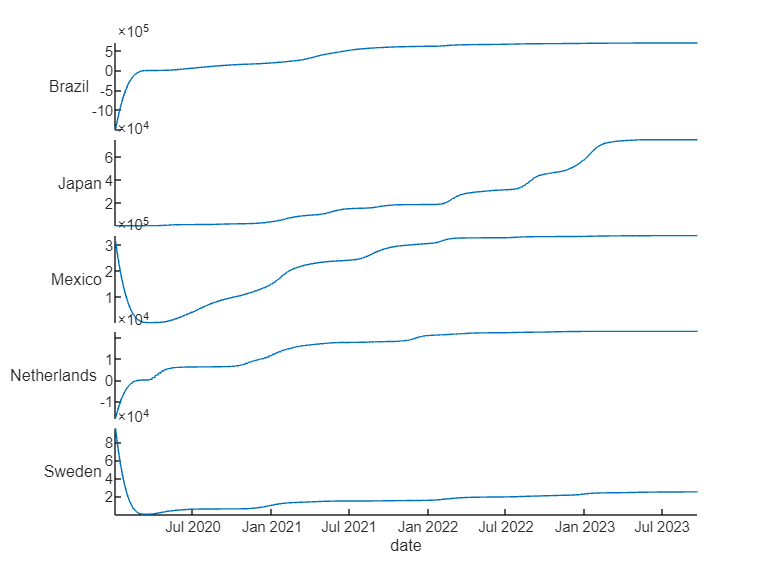

stackedplot(T1)

C = table(T1.Properties.VariableNames', T1{end, :}', 'VariableNames', ["name" "cases"]);

C.duration = sum(T1{:,:} > 0)';

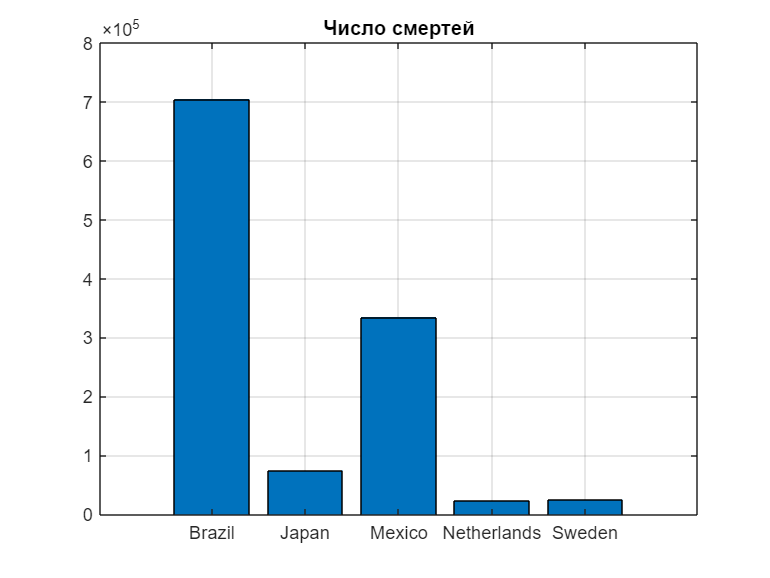

bar(C.cases)
xticklabels(C.name)
grid on
title('Число смертей')

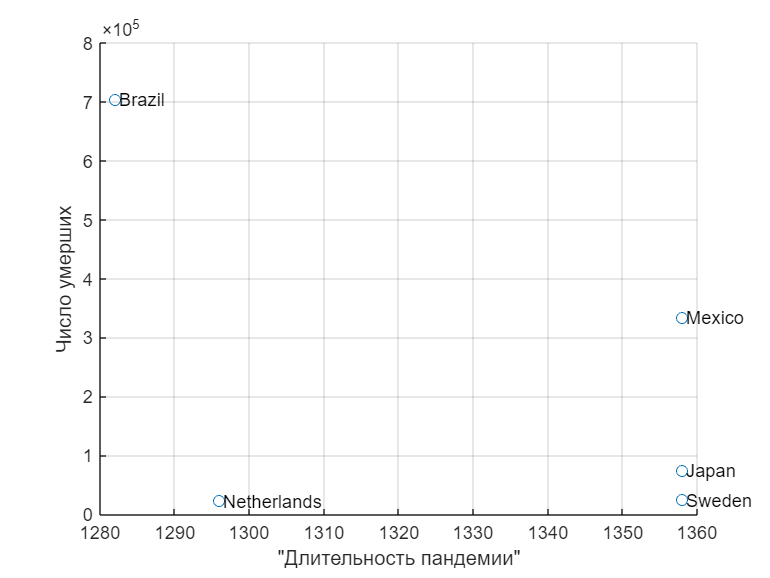

scatter(C.duration, C.cases);
text(C.duration + 0.5, C.cases, C.name)
grid on
xlabel('"Длительность пандемии"')
ylabel('Число умерших')

rc = webread('https://restcountries.com/v3.1/all')

rc = 250×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


rc.name

Dot indexing is not supported for variables of this type.

D = rc.all("fields", "name;population");

Dot indexing is not supported for variables of this type.

D

rc.all("fields", "name;population");

Dot indexing is not supported for variables of this type.

ismember(D.name, ["Brazil","Japan","Mexico","Netherlands","Sweden"])

D = D(ismember(D.name, ["Brazil","Japan","Mexico","Netherlands","Sweden"]))

C1 = outerjoin(C,D,'Keys',{'name'},'MergeKeys',true)

C1.cases_rel = C1.cases ./ C1.population * 100;
C1 = sortrows(C1,'cases_rel')

bar(C1.cases_rel, 'Horizontal',"on")
yticklabels(C1.name)
set(gca,'XGrid','on','YGrid','off')
title('Относительное число зараженных')
xlabel('% от населения')